## Algoritmo A* para encontrar el camino más corto y proceder a la planificación de la trayectoria del robot

### INTRODUCCIÓN

En la búsqueda de algoritmos que nos puedan ayudar a encontrar la trayectoria más corta del robot, se ha decidido la utilización de un mapa de celdillas 2D, que se han dividido en casillas de 1 metro de ancho y de largo, de forma que se puede describir aproximadamente el terreno que debe navegar el robot empleado. El entorno que se describirá en dicho mapa será el asociado con nuestro archivo XML, que describirá el mapa en la simulación, también creado en la realización de este trabajo.

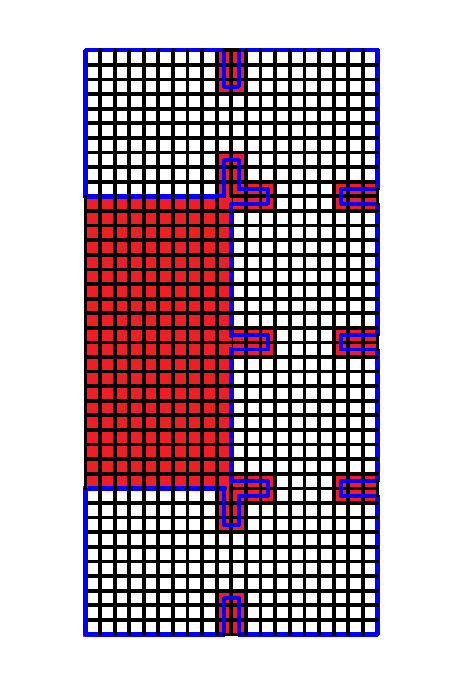

Figura 1. Mapa sin obstaculos que se debe representar de forma matricial en Matlab.

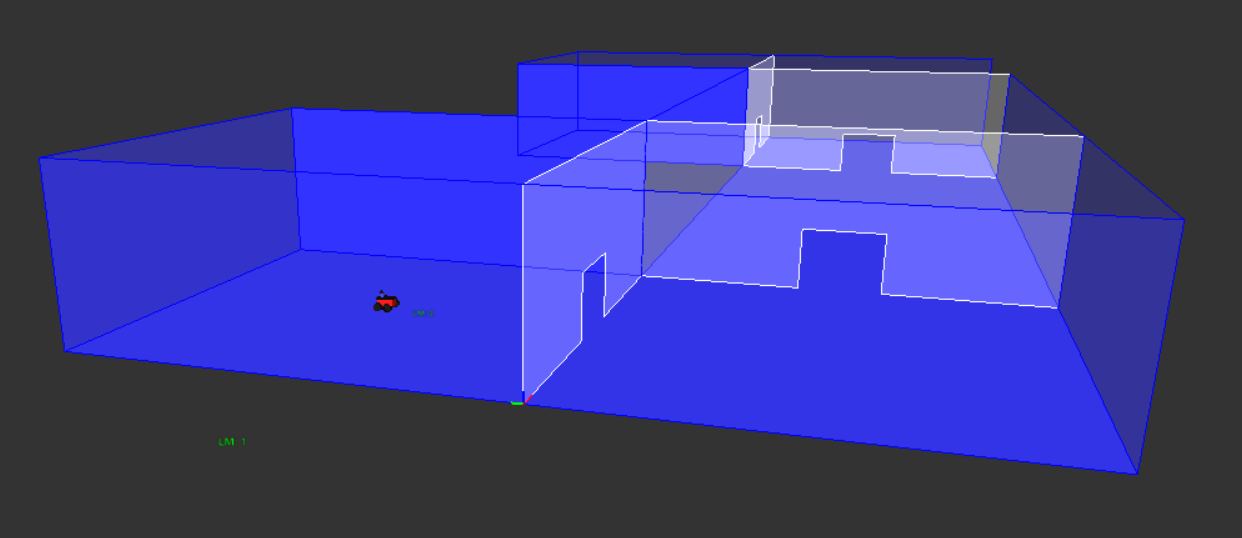

Figura 2. Representación del entorno de trabajo en el simulador Apollo.

Como se puede observar en la Figura 1, esa seria la representación de nuestro mapa sin incluir los obstáculos. Cada celdilla de dicho diagrama será un nodo de nuestro grafo y estará directamente conectado en el grafo con sus vecindades. El buen funcionamiento de esta planificación y de su ejecución con los comandos asociados en el mapa vendrá también dada por la localización de nuestro robot en el mismo, que nos dará pues el punto de partida, la celda en la que se encuentra *Marvin*. 

### MATRIZ 2x2 QUE DESCRIBE EL MAPA

Por un lado, se mantendrá la matriz del entorno, la cual permanecerá siempre inamovible, descrita como el archivo matlab.mat, que incluirá la matriz MMapa. A su vez, mediante el modelado de la matriz de obstáculos (la matriz que va a cambiar según se vaya desarrollando el trabajo) y la combinación con la matriz MMapa, se podrá generar el mapa completo, incluyendo los objetos que se esperan encontrar a lo largo del recorrido del robot; planificando así en consecuencia. Estos mapas, debido a la información completa que tienen del entorno de trabajo, sustituyen la necesidad de incorporar en el proyecto el uso del mapeo, el cual se considera, desde el punto de vista de la asignatura, un problema demasiado grande. Para la incorporación de las matrices se utilizan los siguientes comandos:

%% ETAPA 1: Cargar el mapa y la información de los obstáculos

% Cargamos la matriz que contendrá la matriz MMapa y Mobstaculos 
% que definiran nuestro mapa (ya creadas)
load('matlab.mat');
Map1=MMapa.*MObstaculos; %Combinacion de su info

% Modificamos la matriz para crear el mapa de ocupacion
B=changem(Map1,[0 1],[1 0]);
MAP=binaryOccupancyMap(B);

Una vez cargado nuestro mapa, tal y como se muestra en el anterior código, se puede proceder a la generación de nuestro algoritmo A* para la planificación de la ruta más corta, contando con la posición de inicio (la cual se hallará mediante la localización de nuestro robot en el entorno) y la posición final en cada caso ( la posición que se quiere alcanzar).

### APLICACIÓN DEL ALGORITMO A* EN NUESTRO MAPA

Para la utilización del algoritmo dicho dentro de Matlab y con el propósito de facilitar la misión de planificación se utilizará la Toolbox proporcionada por Matlab: Navigation Robotic Toolbox. Dentro de todas las funciones de planificación que se pueden implementar probaremos unas cuantas en simulación, integrando así todas las funcionalidades del trabajo y escogiendo la planificación más conveniente en función de los resultados obtenidos. Comenzaré con la implementación del conocido A* a modo de saber la mecánica de trabajo con dichos algoritmos en Matlab.

%Map2=binaryOccupancyMap(MMapa);
%show(Map2)
stateSpace=stateSpaceSE2 %Nuestro state space será el predefinido

stateSpace =   stateSpaceSE2 with properties:

                 Name: 'SE2'
          StateBounds: [3×2 double]
    NumStateVariables: 3
             WeightXY: 1
          WeightTheta: 0.1000


stateValidator=validatorOccupancyMap(stateSpace) %Creamos objeto validator

stateValidator =   validatorOccupancyMap with properties:

                   Map: [1×1 binaryOccupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: Inf



% Inicializamos el objeto con las caracteristicas de nuestro mapa
stateValidator.Map=MAP;
stateValidator.ValidationDistance=0.01;
stateSpace.StateBounds=[MAP.XWorldLimits;MAP.YWorldLimits;[-pi,pi]];

%Planificador
planner = plannerRRT(stateSpace,stateValidator);
planner.MaxConnectionDistance = 1.5;

%Posicion inicial y final
start=[5,5,0];
goal=[16,35,0];

%Ver evolucion de nuestroa algoritmos 
rng(100,'twister'); % for repeatable result
[pthObj,solnInfo] = plan(planner,start,goal);

%Cambio de coordenadas para nuestro mapa
trayectoria_def_x = pthObj.States(:,2) 

trayectoria_def_x =     5.0000
    6.0838
    5.3694
    3.9105
    3.7255
    4.1263
    3.6180
    4.5930
    5.9063
    6.8727


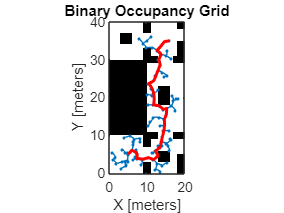

%Mostramos nuestra ruta definitiva con los sucesivos intentos realizados
show(MAP)
hold on
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-'); % tree expansion
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2) % draw path

xlim([0.0 20.0])
ylim([0.0 40.0])

Una vez que se obtiene y se comprueba la gráfica de forma visual en matlab, tenemos que adaptar las coordenadas y los puntos obtenidos al eje de referencia que tenemos en Apollo que no es el mismo que el del mapa de matlab. En la siguiente imagen se mostrará el cambio que se necesita y en el código asociado aplicaremos el cambio de coordenadas.

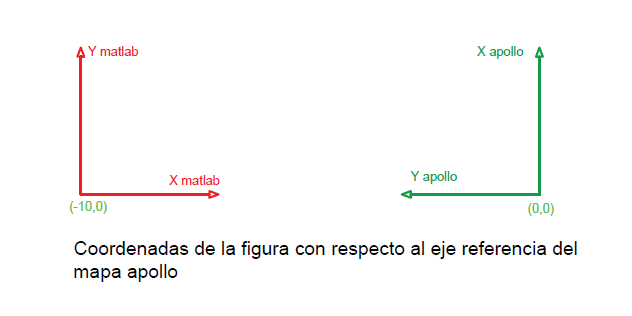

%%CAMBIO DE COORDENADAS
%X mapa = Ymatlab
%Ymapa = -(Xmatlab + 10)
coordenadas_def(:,1) = pthObj.States(:,1)-5;
coordenadas_def(:,2) = pthObj.States(:,2)-5;

% 
% start=goal;
% goal=[5,31,0];
% 
% %Ver evolucion de nuestroa algoritmos 
% rng(100,'twister'); % for repeatable result
% [pthObj,solnInfo] = plan(planner,start,goal);
% 
% %Mostramos nuestra ruta definitiva con los sucesivos intentos realizados
% hold on
% plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-'); % tree expansion
% plot(pthObj.States(:,1),pthObj.States(:,2),'b-','LineWidth',2) % draw path

El codigo anterior genera los objetos necesarios para la planificación y, posteriormente, una vez que todo está listo, podemos elegir entre los diferentes algoritmos ya implementados en Matlab para su elección. Se puede variar la distancia de conexión como se puede apreciar en el código. Esta distancia de conexión, para ser fieles a la generación del grafo buscada se podrá situar en 1 (Recordemos que la relación de celdas que se escogen por defecto es una celda un metro y el mapa está escogido para dicha situación).

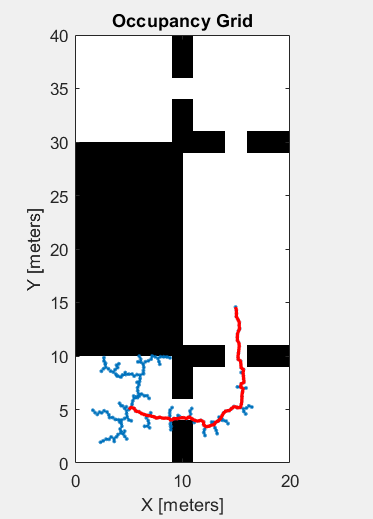

Figura 3. Nuestro mapa de ocupación generado por Matlab a partir de nuestra representación numérica en forma de matriz junto con la planificación. (Nota: habrá que cambiarlo cuando se incluyan los obstáculos fijos próximamente) Esto es lo que nos debería salir del segundo código (o algo parecido).